1. El modelo de Volterra-Lotka estudia la evolución de un sistema formado por dos poblaciones una de depredadores y otra de presas que conforman un ecosistema cerrado.


$$\dot x_1 = ax_1 - cx_1x_2\\
\dot x_2 = -bx_2+dx_1x_2\\
a,b,c,d \in \mathbb{R}^+,$$


donde $x_1$ representa la población de presas; $x_2$ la de depredadores; $a$ la tasa de nacimiento de las presas, que es función de la cantidad de alimento que reciben; $b$ es la tasa de defunción de los depredadores; $c$ y $d$ modelan la interacción entre los depredadores y las presas.

a) Simular el modelo de Volterra-Lotka para parámetros fijos, por ejemplo $a=b=c=d=1$. Emplear para ello tanta Matlab como Simulink. Emplear distintas condiciones iniciales. Obtener tanto un gráfico de la evolución temporal de los estados como el diagrama de fases.

Comenzamos definiendo la función que describe el sistema (ver final del documento). A continuación, establecemos el valor de los parámetros.

[a, b, c, d] = deal(3, 0.5, 0.3, 0.1);

Ahora definimos las condiciones iniciales y un rango de tiempo.

x0 = [15; 10];
t_range = [0, 50];

Empleamos la función `ode45` de MATLAB para resolver el sistema.

[t,x] = ode45(@(t,x)lotka_volterra(t,x,a,b,c,d), t_range, x0);

Y finalmente representamos la solución.

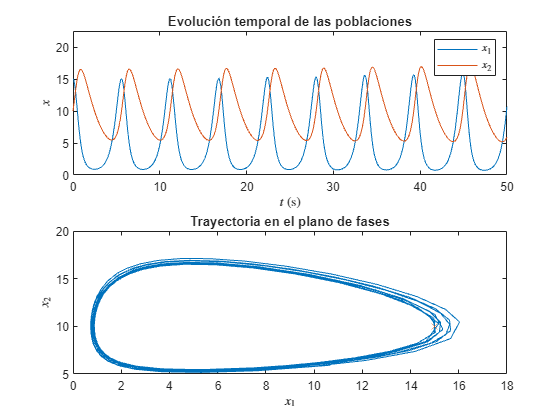

figure(1)
clf
hold off

subplot(2,1,1)
plot(t,x)
title('Evolución temporal de las poblaciones')
ylabel('$x$', 'interpreter', 'latex')
xlabel('$t$ (s)', 'interpreter', 'latex')
ylim([0, max(x0)*1.5])
legend('$x_1$','$x_2$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')

b) Modificar el modelo, de modo que el parámetro $a$ pase a ser un una función periódica $a = \frac{a_0}{2} \sin \left(\omega t\right) + \frac{a_0}{2}$. Estudiar el efecto de la frecuencia en el modelo.

Definimos la función temporal de $a$ junto a una frecuencia.

a_frequency = @(t,a,w) (a/2)*(sin(w*t) + 1);
w = 20;

Resolvemos el sistema.

[t,x] = ode45(@(t,x)lotka_volterra(t,x,a_frequency(t,a,w),b,c,d), t_range, x0);

Y representamos la solución.

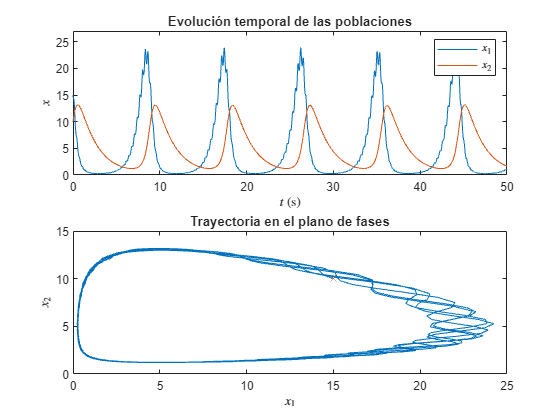

figure(2)
clf
hold off

subplot(2,1,1)
plot(t,x)
title('Evolución temporal de las poblaciones')
ylabel('$x$', 'interpreter', 'latex')
xlabel('$t$ (s)', 'interpreter', 'latex')
ylim([0, max(x0)*1.8])
legend('$x_1$','$x_2$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')

function xdot = lotka_volterra(t,x,a,b,c,d)
%{
INPUTS
------
t : tiempo (s).

x : vector de variables de estado, descrito como un vector columna.
    x(1,1) : población de presas.
    x(2,1) : población de depredadores.

a : tasa de nacimiento de las presas.
b : tasa de defunción de los depredadores.
c,d : modelado de interacción entre presas y depredadores.

OUTPUTS
-------
xdot : vector de variaciones de población.
xdot(1,1) : variación de presas.
xdot(2,1) : variación de depredadores.
%}

xdot(1,1) = +a*x(1,1) - c*x(1,1)*x(2,1);
xdot(2,1) = -b*x(2,1) + d*x(1,1)*x(2,1);
end